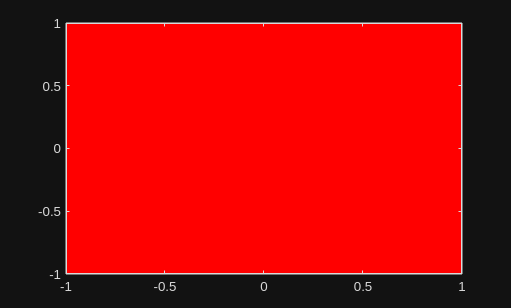

figure("Name","Testando plotar quadrado");

x = [1 1 -1 -1];
y = [-1 1 1 -1];

vertices = [-1 1; 1 1; 1 -1; -1 -1];

fill(x, y, 'r');

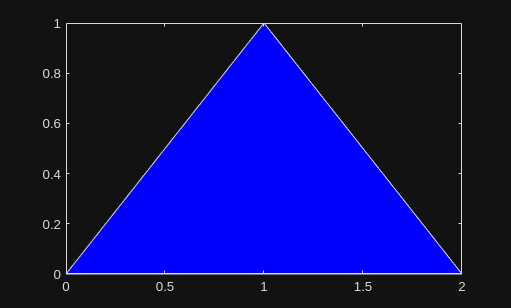


figure("Name", "Testando plotar triangulo");

x = [0 1 2];
y = [0 1 0];

fill(x, y, 'b');

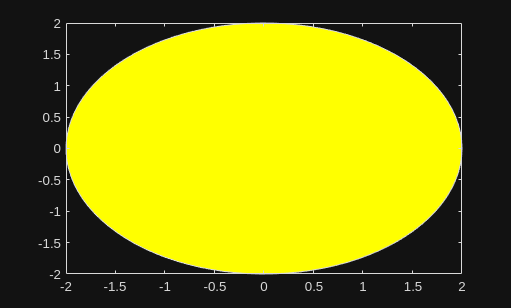


figure("Name","Testando plotar um circulo");

theta = linspace(0, 2*pi, 100);

x = 0;
y = 0;
r = 2;

fill(x + r*cos(theta), y + r*sin(theta), 'y');

## Plotando um mapa


function plotMapa(obs, rob)
    num_obs = size(obs);
    hold on;
    for i=1:num_obs(1)
         fill(obs(i).vertices_xy_m(:,1), obs(i).vertices_xy_m(:,2), 'r');
    end

    plot(rob.x, rob.y, 'wo', 'LineWidth', 2);
    hold off;
end


## Testando a funçao de gerar o mapa a partir do json

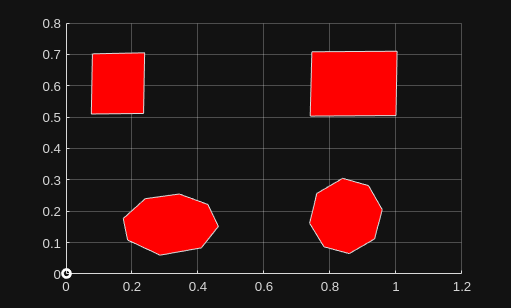

textoJson = fileread('mapa_obstaculos.json');
dados = jsondecode(textoJson);
dados.obstaculos.vertices_xy_m;

rob.x = 0;
rob.y = 0;

figure(Name='Vertices');
plotMapa(dados.obstaculos, rob);
grid on;

## Implementaçao do primeiro algoritmo de geraçao de caminhos

function [map_brushfire] = maptogrid(x_min, x_max, y_min, y_max, obs, grid_step, goal)
    lm = ceil((x_max-x_min)/grid_step);
    hm = ceil((y_max-y_min)/grid_step);
    goal_x_grid = ceil(goal.x/grid_step);
    goal_y_grid = ceil(goal.y/grid_step);

    %gerar o grid
    map_grid = zeros(hm,lm)-1;
    for i=1:obs(end).id %objetos
        for j=1:obs(i).num_vertices %vertices
            obs_grid(i,j).vertices(:) = ceil(obs(i).vertices_xy_m(j,:)/grid_step);
       
        end
        obs_grid(i, end+1).vertices(:) = obs_grid(i,1).vertices(:);
    end
    obs_grid(:,:).vertices;

    %preenchendo o grid com zeros
    x_range = 1:lm;
    y_range = 1:hm;

    [xq, yq] = meshgrid(x_range, y_range); %gera a matriz com as coordenadas

    for i = 1:obs(end).id
        vertices = [obs_grid(i,:).vertices];
        xv = vertices(1:2:end);
        yv = vertices(2:2:end);
        [in, on] = inpolygon(xq, yq,xv ,yv );
        map_grid(in) = Inf;
    end



    map_grid(goal_y_grid, goal_x_grid) = 0;

    next_num = 1;
    terminou = 1;
    while(terminou==1)
        terminou = 0;
        for i=1:hm
            for j=1:lm
                if (map_grid(i,j) ~= -1 && map_grid(i,j) ~= Inf && map_grid(i,j) ~= next_num)
                    
                    if (j < lm && map_grid(i,j+1) == -1)
                        map_grid(i,j+1) = next_num;
                        terminou = 1;
                    end

                    if (j > 1 && map_grid(i,j-1) == -1)
                        map_grid(i, j-1) = next_num;
                        terminou = 1;
                    end
                    if (i < hm && map_grid(i+1, j) == -1)
                        map_grid(i+1, j) = next_num;
                        terminou = 1;
                    end
                    if (i > 1 && map_grid(i-1,j) == -1)
                        map_grid(i-1,j) = next_num;
                        terminou = 1;
                    end
                end
            end
        end
        next_num = next_num+1;
    end
    map_brushfire = map_grid;
end




goal.x = 0.6;
goal.y = 0.5;
map_brushfire = maptogrid(dados.workspace_limites_m.x_min, ...
    dados.workspace_limites_m.x_max, ...
    dados.workspace_limites_m.y_min, ...
    dados.workspace_limites_m.y_max, ...
    dados.obstaculos, ...
    0.05, ...
    goal);

map_brushfire =     20    19    18    17    16    15    14    13    12    11    10     9    10    11    12    13    14    15    16    17    18    19    20    21
    19    18    17    18    17   Inf   Inf   Inf   Inf    10     9     8     9    10    11   Inf   Inf   Inf    17    18    17    18    19    20
    18    17    16   Inf   Inf   Inf   Inf   Inf   Inf     9     8     7     8     9    10   Inf   Inf   Inf   Inf    17    16    17    18    19
    17    16    15   Inf   Inf   Inf   Inf   Inf   Inf   Inf     7     6     7     8   Inf   Inf   Inf   Inf   Inf    16    15    16    17    18
    16    15    14    13   Inf   Inf   Inf   Inf   Inf     7     6     5     6     7     8   Inf   Inf   Inf   Inf   Inf    14    15    16    17
    15    14    13    12    11    10   Inf     8     7     6     5     4     5     6     7   Inf   Inf   Inf   Inf    12    13    14    15    16
    14    13    12    11    10     9     8     7     6     5     4     3     4     5     6     7   Inf     9    10

## Criando funcao pro pathing

function [pathing] = findpathingrid(map_grid, rob, step_grid)
    
    [rw, cl] = size(map_grid);
    
    current_x = ceil(rob.x/step_grid);
    current_y = ceil(rob.y/step_grid);

    %current_weight = map_grid(current_y, current_x);

    while(map_grid(current_y,current_x) ~= 0)
        
    end

end